Clustering test on data

First Technique : Random Cluster Start

Section one : Load data

clear all; close all;
rawData = load('Data.mat');
X = rawData.data.X;
Y = rawData.data.Y;
%randomize data set
[r,~,~] = size(X)

r = 2843

Idx = randperm(r);
X = X(Idx,:,:);
Y = Y(Idx,:);

Section two visual data based on mean of first two dimensions

%Find the mean of first two color maps  
randomPortion =  randi(ceil(length(X)/40))

randomPortion = 137

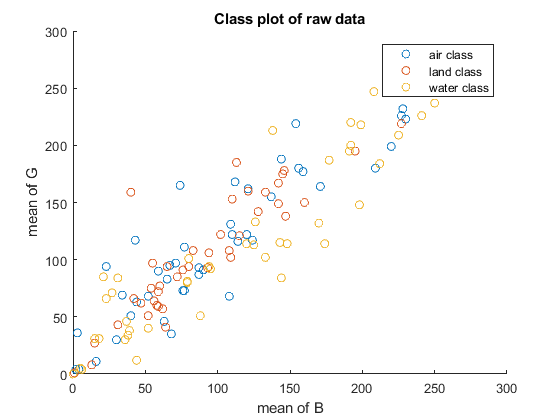

% mean_X = mean(X(1:randomPortion,randomPortion,2),2);
% mean_Y = mean(X(1:randomPortion,randomPortion,3),2);
mean_Y = X(1:randomPortion,end,2);
mean_X = X(1:randomPortion,end,3);
%Plot means of each example in their class colour
figure();
hold on;
for class = 1:3
    plot(mean_X(Y(1:randomPortion)==class),mean_Y(Y(1:randomPortion)==class),'o','MarkerSize',6,'MarkerFaceColor','none')
end
title('Class plot of raw data')
ylabel('mean of G')
xlabel('mean of B')
legend('air class','land class','water class')

Now we have the raw data ready , lets find some cluster nodes to start off the alogrithm

First we are going to spilt our images into only red , green and blue to find seperate centroids in our X array

% pass all the exmaples into the InitCentroids to find the starting centroids
numberOfClusters = 3; % only three classes present in this set
redX = X(:,:,1);
greenX = X(:,:,2);
blueX = X(:,:,3);

[ redCentroids ] = InitCentroids( redX , numberOfClusters , 1 )

redCentroids =     63    59    54    51    50    45    42    41    41    40    38    36    36    34    34    34    31    31    30    30    30    33    36    36    36    37    36    33    32    32    32    32    34    34    35    38    40    39    35    36    35    35    35    36    36    36    35    33    33    32
   165   181   228   247   233   230   234   239   197   158   150   180   197   192   191   166   200   186   178   189   196   165   192   206   196   183   179   157   166   239   235   184   183   200   206   231   226   210   191   194   191   172   162   164   179   182   178   181   191   178
    53    59    54    52    51    51    50    48    52    53    46    48    55    50    55    53    55    54    56    57    60    55    52    50    40    44    53    63    57    55    54    58    59    55    54    61    66    66    73    68    70    72    81    83    76    75    78    69    76    83


[ greenCentroids ] = InitCentroids( greenX , numberOfClusters , 1 )

greenCentroids =    255   255   255   255   255   255   255   255   255   255   255   254   254   253   253   253   254   253   252   250   248   245   242   242   241   237   231   228   226   222   217   216   214   209   208   205   201   198   198   197   198   194   194   193   186   186   190   200   188   171
   142   169   171   174   182   176   168   156   150   123   165   167   168   173   178   177   175   159   147   182   177   174   170   162   183   158   171   177   175   178   160   166   184   181   183   186   178   166   163   139   169   153   127   166   153   159   168   162   155   166
   120   109   108   108   108   112   114   115   114   116   117   118   119   119   119   119   118   115   113   114   115   119   127   138   146   150   148   139   145   152   154   153   150   145   141   139   138   139   140   145   147   143   144   147   153   159   161   164   165   167


[ blueCentroids ] = InitCentroids( blueX , numberOfClusters  , 1)

blueCentroids =     27    84    32   119   147   142   137   130   127   128   132   140   141   143   148   154   155   154   154   157   158   158   158   146   120   132   152   143   147   145   142   147   135   147   141   142   150   141   151   151   149   151   144   150   151   150   150   157   155   155
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   255   255   255   255   255   255   255   255   255   255   255   254   253   252   255
    30    26    25    28    29    29    28    29    29    29    29    31    30    32    34    32    33    34    35    37    42    39    36    35    36    38    39    39    39    40    41    41    39    41    44    48    50    52    57    61    59    63    66    68    72    78    82    88    93    96


Now lets try to assign our data with each of these clusters and see how it performs just using these random data points.

[ redAssignment ] = AssignToClosest( redX ,  redCentroids );
%for each orginal class , find it corsponding index and class and compare it

for class = 1:3
    %find original class index
   class_idx = find(Y==class);
   % find corsponding assignments
   classBelongs = (redAssignment(class_idx));
   %find the unique assignments in that portion 
   values = unique(classBelongs)
   %find how many assignments were in a single class
   for i = 1:length(values)
       numberOfAssignments(i) = length( classBelongs(classBelongs == values(i)) );
   end
   highestAssignments(class) = max(numberOfAssignments)
end

values =      1
     2
     3


highestAssignments = 769

values =      1
     2
     3


highestAssignments =    769   673


values =      1
     2
     3


highestAssignments =    769   673   627


   RedErrorClass = 1 - sum(highestAssignments)/length(Y)

RedErrorClass = 0.2722

[ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
for class = 1:3
    %find original class index
   class_idx = find(Y==class);
   % find corsponding assignments
   classBelongs = (greenAssignment(class_idx));
   %find the unique assignments in that portion 
   values = unique(classBelongs)
   %find how many assignments were in a single class
   for i = 1:length(values)
       numberOfAssignments(i) = length( classBelongs(classBelongs == values(i)) );
   end
   highestAssignments(class) = max(numberOfAssignments)
end

values =      1
     2
     3


highestAssignments =    508   673   627


values =      1
     2
     3


highestAssignments =    508   644   627


values =      1
     2
     3


highestAssignments =    508   644   480


   greenErrorClass =  1 - sum(highestAssignments)/length(Y)

greenErrorClass = 0.4260

[ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
for class = 1:3
    %find original class index
   class_idx = find(Y==class);
   % find corsponding assignments
   classBelongs = (blueAssignment(class_idx));
   %find the unique assignments in that portion 
   values = unique(classBelongs)
   %find how many assignments were in a single class
   for i = 1:length(values)
       numberOfAssignments(i) = length( classBelongs(classBelongs == values(i)) );
   end
   max(numberOfAssignments)
   highestAssignments(class) = max(numberOfAssignments)
end

values =      1
     2
     3


ans = 519

highestAssignments =    519   644   480


values =      1
     2
     3


ans = 592

highestAssignments =    519   592   480


values =      1
     2
     3


ans = 533

highestAssignments =    519   592   533


   blueErrorClass =  1 - sum(highestAssignments)/length(Y)

blueErrorClass = 0.4217

Now acrosss all colour ranges it can be seen that the images aren't getting group together based off their corsponding groups in the labels that we are given .

These previous errors are a bit bias as we dont check to make sure the classes are different for each group assignement and often the highest class in each cluster was 2 meaning that the alogrithm isnt even getting close to accurate groupings.

So now compute the mean of each cluster group now and set it as the centroid and repeat until we converge on a point. Hopefully this will make distinct groupings.

lets try ten iterations to see if we get a reduction of error.

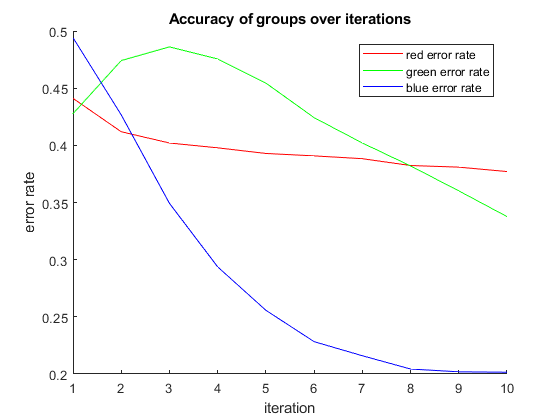

K = 10;
%step the centroids based off assignment
Error  = zeros(K,numberOfClusters);
for k = 1:K
    %compute the new centriods means
    for class = 1:numberOfClusters
       redCentroids(class,:) = mean(redX(redAssignment == class));
       greenCentroids(class,:) = mean(greenX(greenAssignment == class));
       blueCentroids(class,:) = mean(blueX(blueAssignment == class));
    end
    %compute new assignments
    [ redAssignment ] = AssignToClosest( redX ,  redCentroids );
    [ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
    [ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
    %check errors of current iteration of centroids
    [ Error(k,1) , redlabels] = ComputeError( redAssignment , Y );
    [ Error(k,2) , greenlabels ] = ComputeError( greenAssignment , Y );
    [ Error(k,3) , bluelabels ] = ComputeError( blueAssignment , Y );
end
%plot errors over iterations
figure();
hold on;
plot(1:K,Error(:,1),'r');
plot(1:K,Error(:,2),'g');
plot(1:K,Error(:,3),'b');
legend('red error rate','green error rate','blue error rate');
title('Accuracy of groups over iterations');
xlabel('iteration')
ylabel('error rate')

Lets compare the results of each centroid in each setup of RGB centriods by returning the examples back to images to see what has been grouped with what.

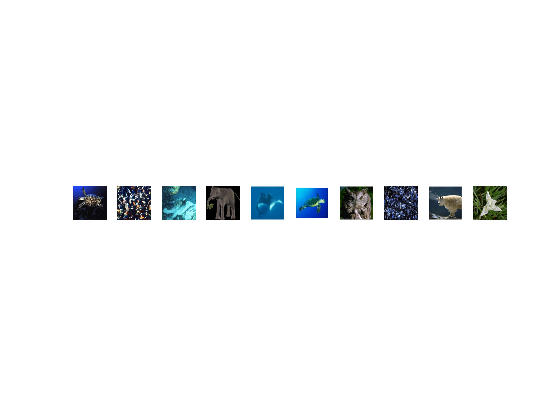

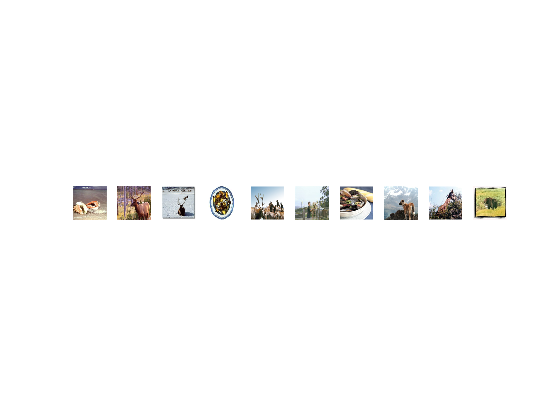

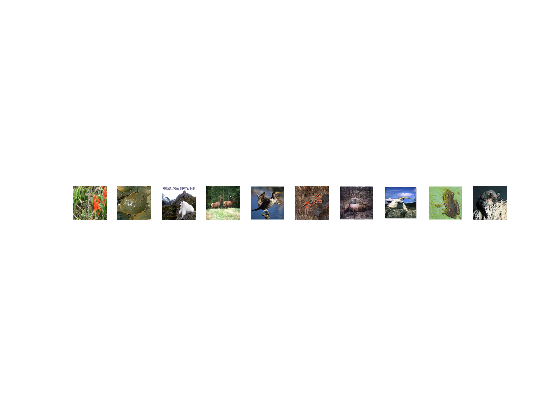

for class = 1 : numberOfClusters   
    figure();
    hold on;
    subplot(1,10,1);
    idx = find(redAssignment==class);
    count = 1;
    for i = 1:10
    remakeImage = uint8(reshape(X(idx(i),:,:),[100 100 3]));
    subplot(1,10,count);
    imshow(remakeImage)
    count = count + 1; 
    end
    axesscale;
    hold off;
end

Now lets try processing based off different larger values of K to see if the groupings get better than our value of K = 10

% re initialisation centroids
[ redCentroids ] = InitCentroids( redX , numberOfClusters , 1 );
[ greenCentroids ] = InitCentroids( greenX , numberOfClusters , 1 );
[ blueCentroids ] = InitCentroids( blueX , numberOfClusters  , 1);
% preform initiallisation assignment
[ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
[ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
[ redAssignment ] = AssignToClosest( redX ,  redCentroids );
%compute steps of centroids
K = 100

K = 100

%step the centroids based off assignment
Error  = zeros(K,numberOfClusters);
for k = 1:K
    %compute the new centriods means
    for class = 1:numberOfClusters
       redCentroids(class,:) = mean(redX(redAssignment == class));
       greenCentroids(class,:) = mean(greenX(greenAssignment == class));
       blueCentroids(class,:) = mean(blueX(blueAssignment == class));
    end
    %compute new assignments
    [ redAssignment ] = AssignToClosest( redX ,  redCentroids );
    [ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
    [ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
    %check errors of current iteration of centroids
    [ Error(k,1) , redlabels] = ComputeError( redAssignment , Y );
    [ Error(k,2) , greenlabels ] = ComputeError( greenAssignment , Y );
    [ Error(k,3) , bluelabels ] = ComputeError( blueAssignment , Y );
    fprintf('iteration %d complete \n',k)
end

iteration 1 complete 
iteration 2 complete 
iteration 3 complete 
iteration 4 complete 
iteration 5 complete 
iteration 6 complete 
iteration 7 complete 
iteration 8 complete 
iteration 9 complete 
iteration 10 complete 
iteration 11 complete 
iteration 12 complete 
iteration 13 complete 
iteration 14 complete 
iteration 15 complete 
iteration 16 complete 
iteration 17 complete 
iteration 18 complete 
iteration 19 complete 
iteration 20 complete 
iteration 21 complete 
iteration 22 complete 
iteration 23 complete 
iteration 24 complete 
iteration 25 complete 
iteration 26 complete 
iteration 27 complete 
iteration 28 complete 
iteration 29 complete 
iteration 30 complete 
iteration 31 complete 
iteration 32 complete 
iteration 33 complete 
iteration 34 complete 
iteration 35 complete 
iteration 36 complete 
iteration 37 complete 
iteration 38 complete 
iteration 39 complete 
iteration 40 complete 
iteration 41 complete 
iteration 42 complete 
iteration 43 complete 
iteration 44 complet

fprintf('the current step iteration of %d is complete \n',K)

the current step iteration of 100 is complete 


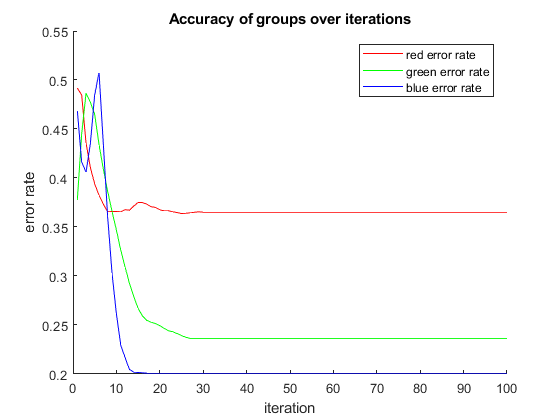

%plot errors over iterations
figure();
hold on;
plot(1:K,Error(:,1),'r');
plot(1:K,Error(:,2),'g');
plot(1:K,Error(:,3),'b');
legend('red error rate','green error rate','blue error rate');
title('Accuracy of groups over iterations');
xlabel('iteration')
ylabel('error rate')
hold off;

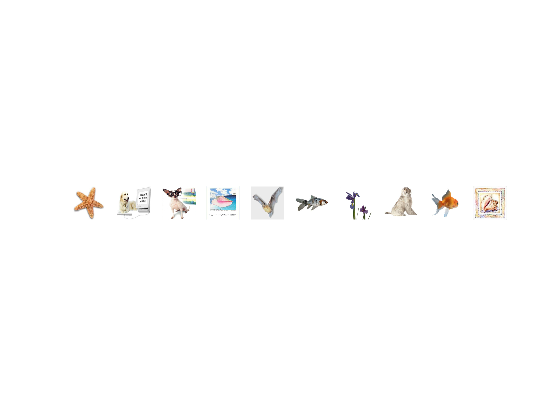

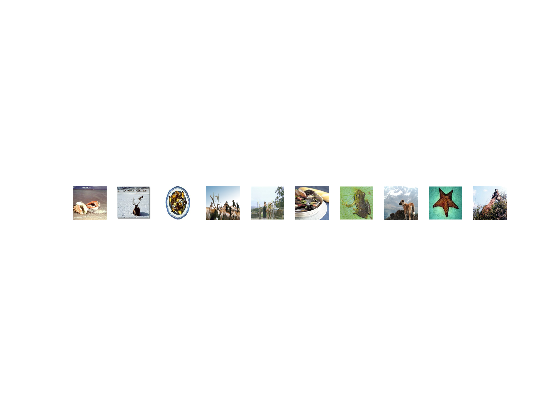

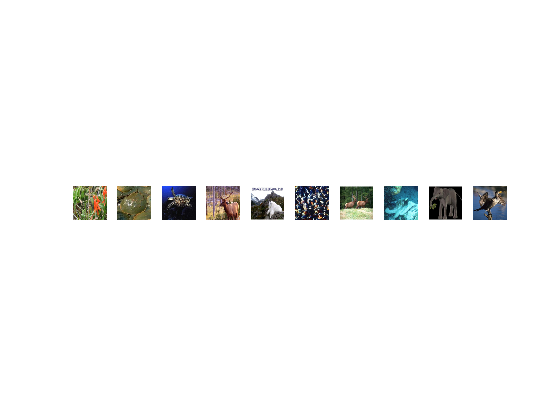

%check what is inside each cluster
for class = 1 : numberOfClusters   
    figure();
    hold on;
    subplot(1,10,1);
    idx = find(greenAssignment==class);
    count = 1;
    for i = 1:10
    remakeImage = uint8(reshape(X(idx(i),:,:),[100 100 3]));
    subplot(1,10,count);
    imshow(remakeImage)
    count = count + 1; 
    end
    %store each cluster by noise factor
    Ndata.X = X(idx,:,:);
    Ndata.Y = Y(idx);
    %save transformed data
    filename = 'NoiseCluster'+string(class)+'.mat';
    save(filename,'Ndata');
    axesscale;
    hold off;
    
end

After checking each cluster out we can see that its not actually clustering around the type of animal in the picture but the noise of the picture , as not all photos are centred and all have different lights so lets re run the whole process on these clusters now that they are grouped with the same noise.

After investigating each cluster we can find that Noisecluster 2 and 3 have most of the files with whitespace examples in cluster 1 only being 40 exmaples.

lets re run the k means clustering over these two new clusters

%NoiseCluster 2 K means clustering
%load data
NoiseCluster = load('NoiseCluster3.mat');
NoiseClusterData = NoiseCluster.Ndata.X;
NoiseClusterLabels = NoiseCluster.Ndata.Y;
%spilt X into RGB data
NoiseClusterRed = NoiseClusterData(:,:,1);
NoiseClusterGreen = NoiseClusterData(:,:,2);
NoiseClusterBlue = NoiseClusterData(:,:,3);
%set the number of clusters wanted
numberOfClusters = 3;
%Run the k means clustering previous used on on the larger set
[redAssignment,greenAssignment,blueAssignment,Error] = KmeansLearner(NoiseClusterRed,NoiseClusterGreen,NoiseClusterBlue,numberOfClusters,NoiseClusterLabels);

iteration 1 complete 
iteration 2 complete 
iteration 3 complete 
iteration 4 complete 
iteration 5 complete 
iteration 6 complete 
iteration 7 complete 
iteration 8 complete 
iteration 9 complete 
iteration 10 complete 
iteration 11 complete 
iteration 12 complete 
iteration 13 complete 
iteration 14 complete 
iteration 15 complete 
iteration 16 complete 
iteration 17 complete 
iteration 18 complete 
iteration 19 complete 
iteration 20 complete 
iteration 21 complete 
iteration 22 complete 
iteration 23 complete 
iteration 24 complete 
iteration 25 complete 
iteration 26 complete 
iteration 27 complete 
iteration 28 complete 
iteration 29 complete 
iteration 30 complete 
iteration 31 complete 
iteration 32 complete 
iteration 33 complete 
iteration 34 complete 
iteration 35 complete 
iteration 36 complete 
iteration 37 complete 
iteration 38 complete 
iteration 39 complete 
iteration 40 complete 
iteration 41 complete 
iteration 42 complete 
iteration 43 complete 
iteration 44 complet

%check whats going on with each cluster
examplesWanted = 20;
% The red pixel range only makes one clear cluster
    disp('This is the breakdown of clusters inside red pixel range')

This is the breakdown of clusters inside red pixel range


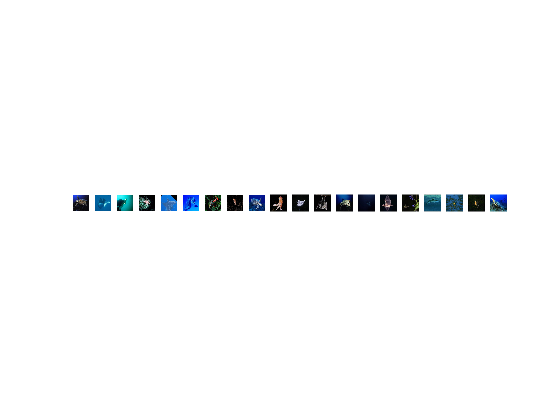

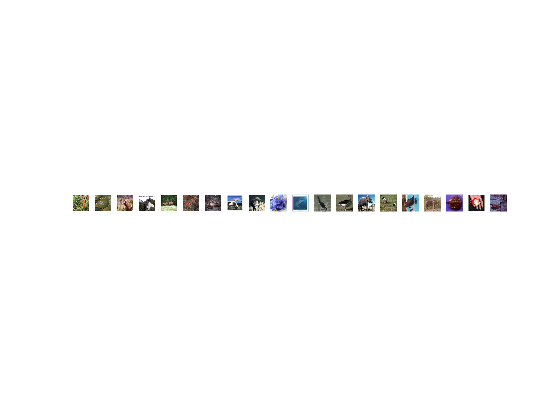

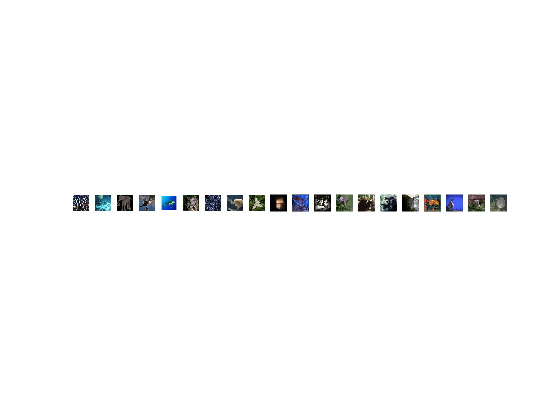

    ShowInsideCluster(numberOfClusters,examplesWanted,NoiseClusterData,redAssignment);

    disp('This is the end for inside red pixel range')

This is the end for inside red pixel range


% green pixel range only makes one clear cluster
    disp('This is the breakdown of clusters inside green pixel range')

This is the breakdown of clusters inside green pixel range


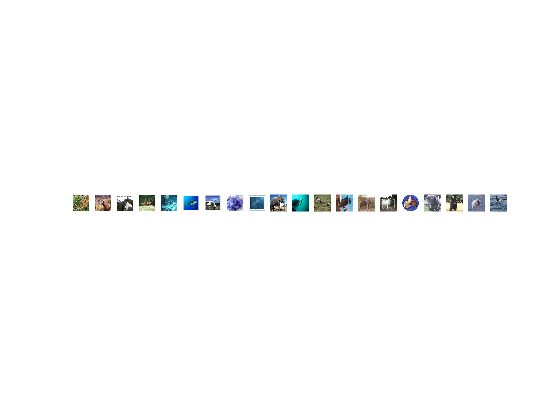

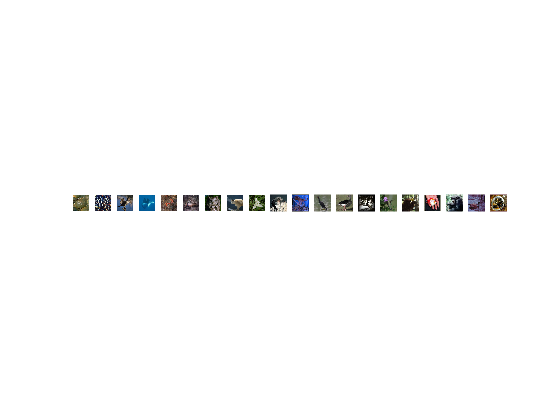

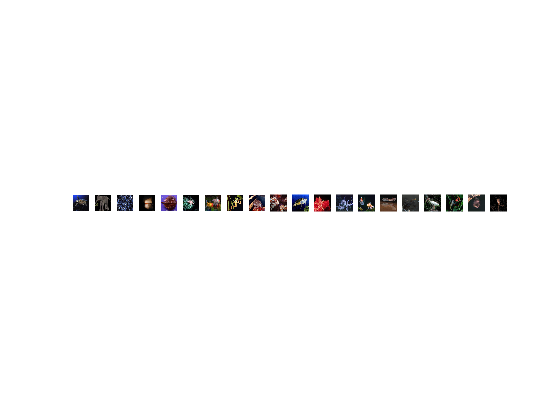

    ShowInsideCluster(numberOfClusters,examplesWanted,NoiseClusterData,greenAssignment);

    disp('This is the end for inside green pixel range')

This is the end for inside green pixel range


% the blue range only makes two clear clusters
    disp('This is the breakdown of clusters inside blue pixel range')

This is the breakdown of clusters inside blue pixel range


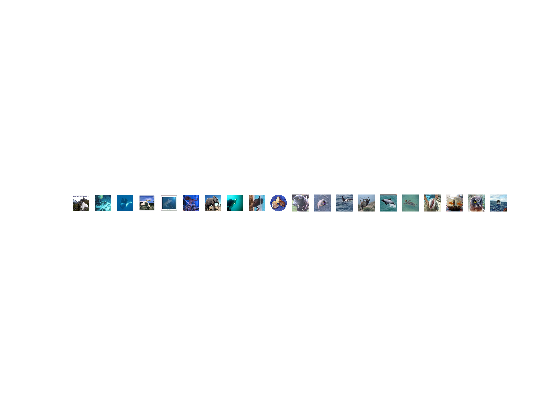

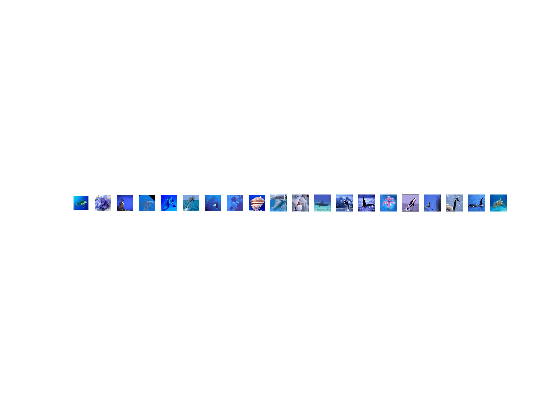

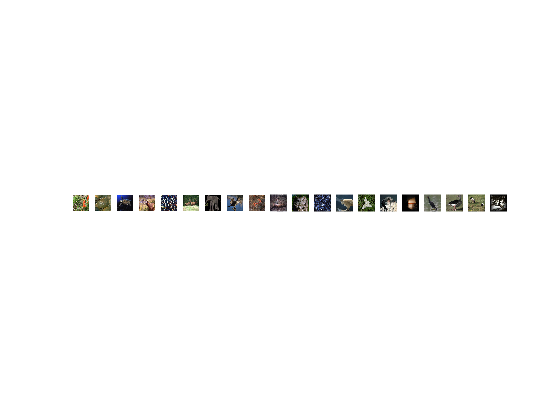

    ShowInsideCluster(numberOfClusters,examplesWanted,NoiseClusterData,blueAssignment);

    disp('This is the end for inside blue pixel range')

This is the end for inside blue pixel range


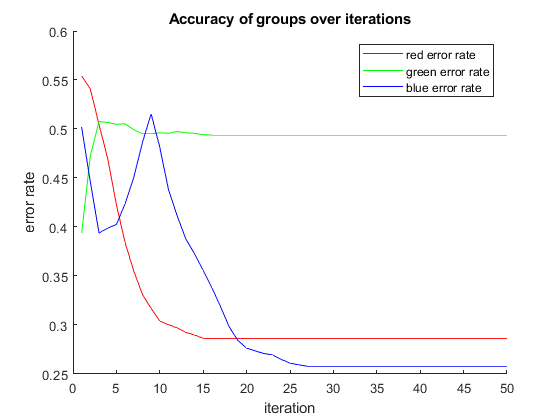

%plot the error graph
figure();
hold on;
plot(1:30,Error(:,1),'r');
plot(1:30,Error(:,2),'g');
plot(1:30,Error(:,3),'b');
legend('red error rate','green error rate','blue error rate');
title('Accuracy of groups over iterations');
xlabel('iteration')
ylabel('error rate')
hold off;

Now we can see that the green pixel range is performing the best in this cluster , we can start to see different subsets occuring so lets breakdown these clusters again and see how we perform.

%breakdown NoiseCluster3 into three clusters again to perform inception
for class = 1 : numberOfClusters
   idx = find(greenAssignment==class)
   inception.X = NoiseClusterData(idx,:,:);
   inception.Y = NoiseClusterLabels(idx);
   filename = 'InceptionCluster'+string(class)+'.mat';
   save(filename,'inception');
end

idx =      1
     4
     5
     7
     8
    13
    16
    21
    23
    27


idx =      2
     6
    10
    11
    12
    14
    15
    18
    19
    20


idx =      3
     9
    17
    22
    34
    77
    91
   116
   117
   124
